# SASNE running example

data = readmatrix('data/imbalanced_test.txt');

[sasne_out,Z] = SASNE(data);

constructing graph...
Smallest k is 20 in layer 1


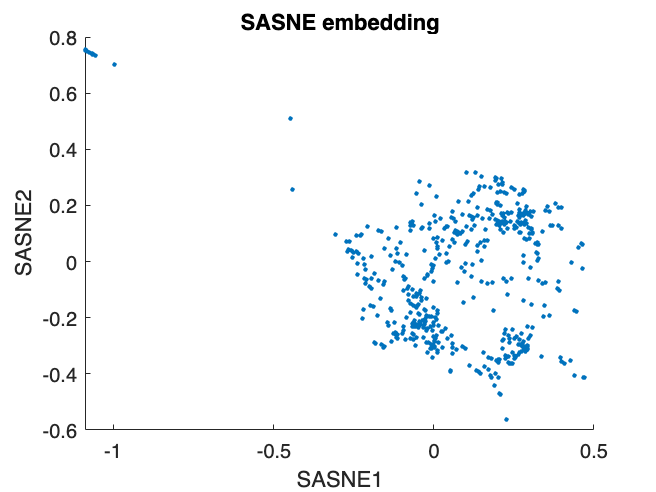

figure
scatter(sasne_out(:,1),sasne_out(:,2),5,'filled')
title('SASNE embedding')
xlabel('SASNE1')
ylabel('SASNE2')

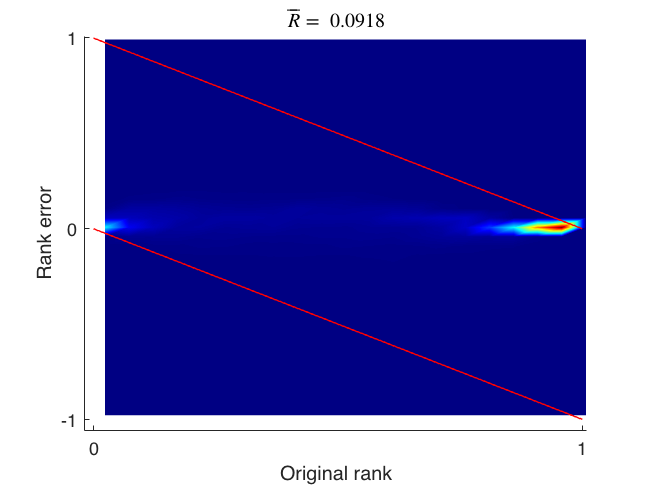

D_original = pdist(Z,'euclidean');
D_sasne = pdist(sasne_out,'euclidean');
RRP(D_original,D_sasne);

clear D_original D_sasne ans